# Optimización en redes. Problema de camino mínimo

## Resumen.

En este live script se verán los procedimientos de Matlab que resuelven el problema de camino mínimo para redes dirigidas.

## Problema de camino mínimo.

Se parte del digrafo  G=(V,U), siendo V el conjunto de vértices o nodos, se supone V={1,2,..,n} y U el conjunto de arcos. Se lee dicho grafo a partir de la lista de arcos:

s2=[1 ; 1 ;  2 ;  2 ;  2 ;  3 ;  5 ]; 

t2=[2 ;  3 ;  3 ;  4 ;  5 ;  5 ;  4]; 

G2 = digraph(s2,t2)

G2 =   digraph with properties:

    Edges: [7×1 table]
    Nodes: [5×0 table]


Una vez definida la estructura de digrafo, se incorporan los pesos de los arcos:

peso2 = [ 100 ; 150 ; 30 ; 110 ; 220 ; 105 ; 40 ];

Y se define la estructura de la red dirigida

 R2 = digraph(s2,t2,peso2) 

R2 =   digraph with properties:

    Edges: [7×2 table]
    Nodes: [5×0 table]


La representación gráfica de esta red se obtiene con la función *plot* con

los siguientes argumentos:

est_grafica = plot(R2,'Edgelabel',R2.Edges.Weight);

Observación: para dibujar esta red de una forma más ordenada, hay que recordar las coordenadas con las que se representan los nodos con la estructura gráfica.

est_grafica

est_grafica =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'}
     EdgeLabel: {'100'  '150'  '30'  '110'  '220'  '105'  '40'}
         XData: [2.5000 2 3 2 2.5000]
         YData: [5 4 3 1 2]
         ZData: [0 0 0 0 0]

  Show all properties


A partir de esta estructura,

est_grafica.XData

ans =     2.5000    2.0000    3.0000    2.0000    2.5000


est_grafica.YData

ans =      5     4     3     1     2


se puede corregir, por ejemplo, la localización del nodo 4:

est_grafica.XData(4)=1;
est_grafica.YData(4)=2;

Y para que quede más centrado:

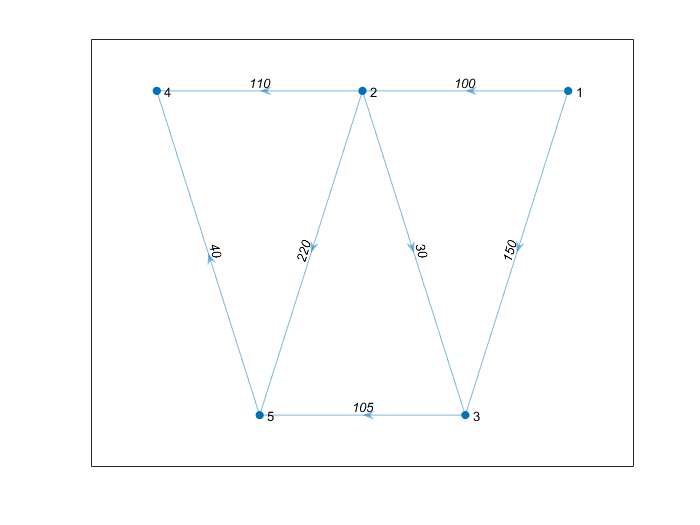

est_grafica.XData=[4 2 3 0 1];
est_grafica.YData=[1 1 0 1 0];

### Solución del problema camino mínimo entre dos nodos concretos

Para identificar el camino mínimo entre un par de nodos concretos, se utiliza la función shortestpath, que identifica en un vector la sucesión de nodos del camino (p) y la distancia mínima alcanzada (d):

[p,d]=shortestpath(R2,1,5);


Para acceder a la información de la solución:

p

p =      1     2     3     5


d

d = 235

### Solución del problema camino mínimo entre dos nodos concretos

Para identificar los caminos mínimos que salen de un nodo concreto, se utiliza la función shortestpathtree, que identifica en la estructura TR la solución, el vector u (de dimensión n) identifica la distancia  mínima a cada nodo desde el nodo inicial, y el vector v (de dimensión m) especifica si cada uno de los arcos pertenece (1) o no (0):

[TR,u,v] = shortestpathtree(R2,1);


Para acceder a la información de la solución:

TR

TR =   digraph with properties:

    Edges: [4×2 table]
    Nodes: [5×0 table]


u

u =      0   100   130   210   235


E

E = 7×1 logical array
   1
   0
   1
   1
   0
   1
   0


Para identificar la solución, 

TR.Edges

ans = 4×2 table
    EndNodes    Weight
    ________    ______

     1    2      100  
     2    3       30  
     2    4      110  
     3    5      105  


TR.Edges.EndNodes(2,1)

ans = 2

TR.Edges.EndNodes(2,2)

ans = 3

TR.Edges.Weight(2)

ans = 30

### Visualización de la solución del problema de camino mínimo

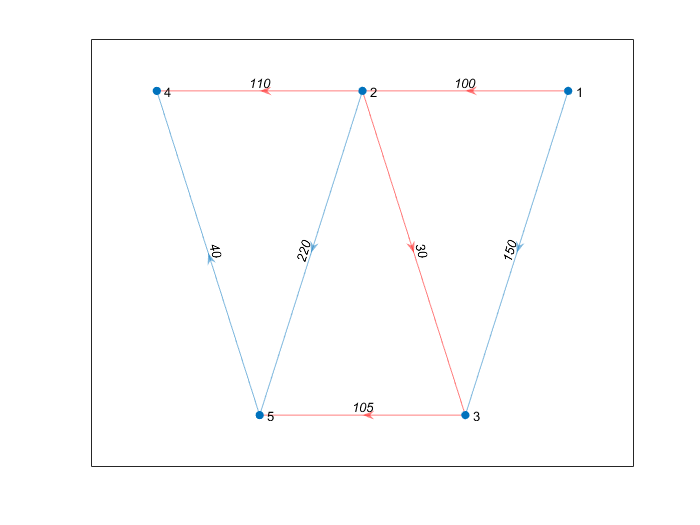

est_grafica=plot(R2,'Edgelabel',R2.Edges.Weight); 
est_grafica.XData=[4 2 3 0 1];
est_grafica.YData=[1 1 0 1 0];
highlight(est_grafica,TR,'Edgecolor','r'); 